# Introduction to Projectile Motion

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Modeling projectile motion for a point mass is relatively easy, so it's a good starting point to review working in MATLAB and Simulink. First, we have to define our system. Let $m$ be the mass of our point in kilograms, $g = 9.81$ be the acceleration due to gravity in meters per second squared, and $p$ be the position of our mass at time $t$. Remember that the Newtonian equations of motion state that the sum of all forces on our object is equal to the mass times the acceleration of the object, that is $\displaystyle m\frac{d^2p}{dt^2} = \sum_i F_i$.

## Free Fall

The simplest projectile motion problem is to throw our point mass directly upwards, with a magnitude of $v_0$ meters per second. In this case, we know that only a single force, the downward pull of gravity, acts on our mass. Therefore, to solve the equation for a position, $p(t)$, as a function of time, we need to know the initial velocity, $v_0$, and the initial position, $x_0$, of our mass.

Putting this together, the differential equation describing our model becomes

$m\frac{d^2p}{dt^2} = -mg$ with the initial conditions $\left.\frac{dp}{dt}\right|_{t=0} = v_0$ and $p(0) = p_0$.

Rather than using equations from calculus to solve for $p$, let's simulate the position of our mass step-by-step. 

### Numerical Approximation

First, we define our spatial coordinate system. Let's assume that our point mass starts at the origin. We define "upwards" to be in the positive *y* direction. 

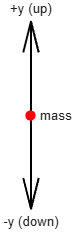

This is only a one-dimensional system for the moment. Therefore, we can treat all of our values as signed scalars.

Now, gravitational acceleration is pulling *downwards* in the $y$ direction, so the acceleration of our point mass is 

$a = -g \approx -9.81 \,\frac{\text{m}}{\text{s}^2}$.

We also know that we can approximate $a$ at the $i^{\text{th}}$ time step as:


$$a  \approx \frac{v_i - v_{i-1}}{t_i-t_{i-1}}$$


where $v_k$ is the velocity at time $t_k$. If our time step is consistent such that $\text{dt} = t_i-t_{i-1}$ for any value of $i$, then we can solve this equation iteratively using [symplectic Euler](https://en.wikipedia.org/wiki/Semi-implicit_Euler_method):


$$v_i \approx a(t_i-t_{i-1})+v_{i-1} = v_{i-1}-g\cdot \text{dt}.$$



$$v_{i-1} \approx v_{i-2}-g\cdot \text{dt} \Rightarrow v_i \approx v_{i-2}-2g\cdot \text{dt}$$



$$\vdots$$



$$v_i \approx v_0-i\cdot g \cdot \text{dt}$$


We can also integrate the velocity to know the displacement (the height, $p$) at every time $t_i$. Using this semi-implicit Euler's method for first-order integration:

$p_i \approx p_{i-1} + v_i\cdot \text{dt}$.

This means that if we know $v_0$, $p_0$, and $\text{dt}$, we can iteratively approximate all future values of both $v_i$ and $p_i$ as long as our model holds. 

#### Set Up Variables

m = 6;     % mass (kg)
g = 9.81;  % gravitational acceleration (m/s^2)
v0 = 10;   % initial vertical velocity (m/s)
p0 = 0;    % initial position (m)
dt = 0.01; % timestep (s)

Run this section to compute one time step of the numerical approximation. 

 
vNext = v0-g*dt;        % v1 = v0+a*dt
pNext = p0+vNext*dt;    % p1 = p0+v1*dt 

tl = tiledlayout(2,1);
title(tl,"The Position of the Mass")
nexttile
v = plot([0 dt],[v0 vNext]);
ylabel("Velocity $v$ (m/s)",Interpreter="latex")
nexttile
p = plot([0 dt],[p0 pNext]);
ylabel("Displacement $p$ (m)",Interpreter="latex")
xlabel("Time (s)")
% Define a table of values
T = table(1, p0, v0, vNext, pNext, ...
    'VariableNames', {'Step', 'InitialPosition', 'InitialVelocity', 'vNext = v0-g*dt', 'pNext = p0+vNext*dt'});
disp(T)

Iterate and update the plot and table:

 
vPrev = vNext;   % Set up v_{i-1}
pPrev = pNext;   % Set up p_{i-1}

vNext = vPrev-g*dt;         % Compute v_i = v_{i-1}-g*dt
pNext = pPrev + vNext*dt;   % Compute p_i = p_{i-1}+v_i*dt

v.XData = [v.XData v.XData(end)+dt]; % Add another point t_i
v.YData = [v.YData vNext];           % Add another point v_i
p.XData = [p.XData p.XData(end)+dt]; % Add another point t_i
p.YData = [p.YData pNext];           % Add another point p_i
% Append new step to the table and display the result
T = [T; {T.Step(end)+1 pPrev vPrev vNext pNext}];
disp(T)

  **Try**. Run this section of code repeatedly. What happens to your plots? And your table?

**Note: **If you encounter errors, try going back to the initial step and working through the iterations again.

#### How Many Timesteps?

As the motion is symmetric, launching from ground level, $p=0$, and assuming no air resistance, we can calculate the flight time as: 


$$p(t) = -\frac{g}{2}t^2 + v_0t$$
                

The mass has returned to the ground when $p(t_{\text{end}}) = 0$ so solving the quadratic equation:


$$0 = -\frac{g}{2}t^2+v_0t$$
            


$$\Rightarrow t = -\frac{v_0\pm \sqrt{v_0^2}}{-g}$$
 

so $t_0=0$, because we start at ground level, and $t_{\text{end}} = \frac{2v_0}{g}$.

  **Try**. How many time steps, `n_timesteps`, are required to complete the full parabola from $t_0=0$ to $t_{\text{end}}=\frac{2v_0}{g}$?

 **Reflect**. Is `n_timesteps` required to be an integer? Why or why not? 

### Simulate and Plot in 1D

More generally, we may launch the projectile from positions other than $p=0$. This requires a derivation starting from $p(t) = -\frac{g}{2}t^2 + v_0t + p_0$ and concluding that $t_{\text{end}} = \frac{v_0+\sqrt{v_0^2+2gp_0}}{g}$. Details are left as an exercise to the reader.

 
m = 6;    % mass (kg)
g = 9.81;                        % gravitational acceleration (m/s^2)
a = -g;                          % acceleration downwards due to gravity
v0 = 10;   % vertical velocity (m/s)
p0 = 0; % initial vertical position (m)
dt = 0.01;       % timestep (s)
ShowAnimation = false;             % Choose whether or not to create an animation
tEnd = (v0+sqrt(v0^2+2*g*p0))/g;
t = 0:dt:tEnd;                   % creating time array
TotTimeSteps = length(t);

v = zeros(1,TotTimeSteps); % creating empty velocity vector
p = zeros(1,TotTimeSteps); % creating empty position vector

p(1) = p0; % Initial position
v(1) = v0; % Initial velocity

for i = 2:TotTimeSteps
    v(i) = v(i-1) - g*dt;
    p(i) = p(i-1) + v(i)*dt;
end

figure
tl = tiledlayout(2,1);
title(tl,"A Parabolic Path Stopping at 0 on the Descent")
nexttile
plot(t, v)
ylabel("Velocity (m/s)")

nexttile
plot(t, p)
ylabel("Displacement y (m)")
xlabel("Time (s)")
if ShowAnimation
    figure
    pts = scatter(0,p0,"filled");
    hold on
    pLine = plot(0,p0);
    VerticalLines = round(linspace(min(p),max(p),5),1);
    for yVal = VerticalLines
        yline(yVal)
        text(1,yVal,string(yVal))
    end
    hold off
    title("Animation of Projectile Motion")
    axis off
    xlim([-1 1])              % Set window size to be convenient
    ylim([min(p)-0.1 max(p)+1])   % for the animation
    for i = 2:(TotTimeSteps)
        pts.YData = p(i);
        pLine.XData = zeros(1,i);
        pLine.YData = p(1:i);
        drawnow
    end
end

  **Try**.

- Change the value of $m$. What does this do to your velocity and displacement? Why?

- Change the value of $v_0$. What does this do to your velocity and displacement? Why?

- Change the value of $dt$. What does this do to your velocity and displacement? Why?

- Can you get a MATLAB error? How and why?

## 2D Projectile Motion

Next, let's add some horizontal velocity. The vertical motion remains the same, but now the projectile moves in the x-direction as well. Because the directions are independent, we can solve each component of the motion separately. 

We can use some interactive controls to set this up:

v0 = 50;    % initial velocity m/s
angle = 45; % initial angle (degrees)
x0 =0;    % initial x position
y0 =0;    % initial y position
 

 **Exercise 1. **Use the functions `sind` and `cosd` to compute the initial vertical ($v_{y_0}$ or `vy0`) and horizontal ($v_{x_0}$ or `vx0`) components of the initial velocity.

 **Exercise 2.**

Copy the 1D example and modify the code to solve the 2D problem by properly tracking and displaying both the $x$ and $y$ components of the parabolic path. 

## Modeling Projectiles in Simulink®

What if we now add air resistance?

The drag force depends on the velocity and thus changes at every point in time. This means that all the equations need to be written differently. Let's use Simulink to model this, since it is designed to solve differential equations. 

### Implementing a 1D Projectile

Let's start by recreating the 1D scenario solving $\frac{d^2p}{dt^2} = -g$ with $p'(0) = 50$ and $p(0)=10$ in Simulink. The expectation is that you are familiar with the content in [Simulink Onramp](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink). Instructions to build the model are included in the model.

open("Projectile_1D.slx")

### Adding Drag to a 1D Projectile

Recall that the drag is proportional to the square of the velocity and acts in the opposite direction. 


$$\frac{d^2p}{dt^2} = -g-\text{sign}\left(\frac{dp}{dt}\right)\alpha\left(\frac{dp}{dt}\right)^2$$


where $\alpha = \frac{1}{2m} \rho C_d A$ with units of $\frac{1}{\text{meters}}$ is a lumped parameter that tracks how physical characteristics of the mass impact the [drag force](https://en.wikipedia.org/wiki/Drag_coefficient) and the $-\text{sign}\left(\frac{dp}{dt}\right)$ encodes the fact that drag opposes motion. For your initial solution, use $\alpha = 0.1$.

In Simulink, the RHS looks like

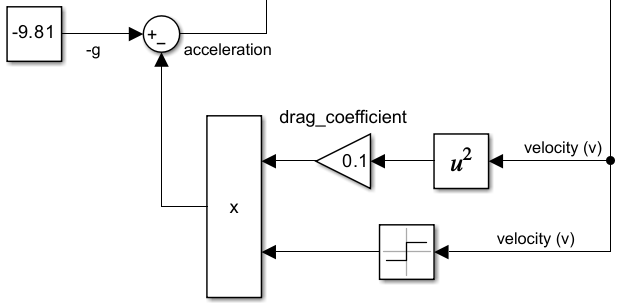

The five new blocks you need are:

- Gain 

- Sign

- Square

- Product

- Sum

 **Pro-tip. **Remember that Ctrl-R (or Cmd-R on a Mac) will rotate a block, and Ctrl-I will flip a block.

open("Projectile_1D_WithDrag.slx")

 **Reflect**. 

- What has changed in the velocity and position plots with the inclusion of drag?

- If you increase the drag coefficient, will your mass fly higher or lower than before?

- When does your mass hit the ground? 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))